syms a2 b1 c1 c2 k x y
general = [(2*b1*x/k) + b1 - c1*y, c1*x ; c2*y, c2*x - a2]

$$general = \left(\begin{array}{cc} b_{1}-c_{1}\,y+\frac{2\,b_{1}\,x}{k} & c_{1}\,x\\ c_{2}\,y & c_{2}\,x-a_{2} \end{array}\right)$$

A_ss1 = [b1 0 ; 0 -a2]

$$A\_ss1 = \left(\begin{array}{cc} b_{1} & 0\\ 0 & -a_{2} \end{array}\right)$$

A_ss2 = [3*a2*b1/(k*c2) a2*c1/c2 ; (c2*b1/c1)*(1-a2/c2*k) 0]

$$A\_ss2 = \left(\begin{array}{cc} \frac{3\,a_{2}\,b_{1}}{c_{2}\,k} & \frac{a_{2}\,c_{1}}{c_{2}}\\ -\frac{b_{1}\,c_{2}\,\left(\frac{a_{2}\,k}{c_{2}}-1\right)}{c_{1}} & 0 \end{array}\right)$$

A_ss3 = [3*b1 k*c1; 0 k*c2 - a2]

$$A\_ss3 = \left(\begin{array}{cc} 3\,b_{1} & c_{1}\,k\\ 0 & c_{2}\,k-a_{2} \end{array}\right)$$

[EV1,ev1] = eig(A_ss1)

$$EV1 = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

$$ev1 = \left(\begin{array}{cc} b_{1} & 0\\ 0 & -a_{2} \end{array}\right)$$

[EV2,ev2] = eig(A_ss2)

$$EV2 = \begin{array}{l} \left(\begin{array}{cc} \frac{c_{1}\,\left(3\,a_{2}\,b_{1}+\sigma_{1}\right)}{2\,b_{1}\,c_{2}\,k\,\left(c_{2}-a_{2}\,k\right)} & \frac{c_{1}\,\left(3\,a_{2}\,b_{1}-\sigma_{1}\right)}{2\,b_{1}\,c_{2}\,k\,\left(c_{2}-a_{2}\,k\right)}\\ 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{a_{2}\,b_{1}\,\left(4\,{c_{2}}^{2}\,k^{2}-4\,a_{2}\,c_{2}\,k^{3}+9\,a_{2}\,b_{1}\right)} \end{array}$$

$$ev2 = \left(\begin{array}{cc} \frac{3\,a_{2}\,b_{1}+\sqrt{a_{2}\,b_{1}\,\left(4\,{c_{2}}^{2}\,k^{2}-4\,a_{2}\,c_{2}\,k^{3}+9\,a_{2}\,b_{1}\right)}}{2\,c_{2}\,k} & 0\\ 0 & \frac{3\,a_{2}\,b_{1}-\sqrt{a_{2}\,b_{1}\,\left(4\,{c_{2}}^{2}\,k^{2}-4\,a_{2}\,c_{2}\,k^{3}+9\,a_{2}\,b_{1}\right)}}{2\,c_{2}\,k} \end{array}\right)$$

[EV3,ev3] = eig(A_ss3)

$$EV3 = \left(\begin{array}{cc} -\frac{c_{1}\,k}{a_{2}+3\,b_{1}-c_{2}\,k} & 1\\ 1 & 0 \end{array}\right)$$

$$ev3 = \left(\begin{array}{cc} c_{2}\,k-a_{2} & 0\\ 0 & 3\,b_{1} \end{array}\right)$$

a_1 = subs(ev1,[b1,a2,c1,c2,k],[1,0.5,0.01,0.005,1000])

$$a\_1 = \left(\begin{array}{cc} 1 & 0\\ 0 & -\frac{1}{2} \end{array}\right)$$

a_2 = subs(ev2,[b1,a2,c1,c2,k],[1,0.5,0.01,0.005,1000])

$$a\_2 = \left(\begin{array}{cc} \frac{3}{20}+\frac{\sqrt{19999791}\,\mathrm{i}}{20} & 0\\ 0 & \frac{3}{20}-\frac{\sqrt{19999791}\,\mathrm{i}}{20} \end{array}\right)$$

a_3 = subs(ev3,[b1,a2,c1,c2,k],[1,0.5,0.01,0.005,1000])

$$a\_3 = \left(\begin{array}{cc} \frac{9}{2} & 0\\ 0 & 3 \end{array}\right)$$

x = [200 80]';
tspan = 0:0.1:100;
[X,Y] = ode45(@ODEfcn,tspan,x)

X =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


Y =   200.0000   80.0000
  199.5966   84.0960
  198.3782   88.3663
  196.3447   92.7777
  193.5134   97.2903
  189.9189  101.8586
  185.6136  106.4310
  180.6617  110.9535
  175.1496  115.3655
  169.1750  119.6062


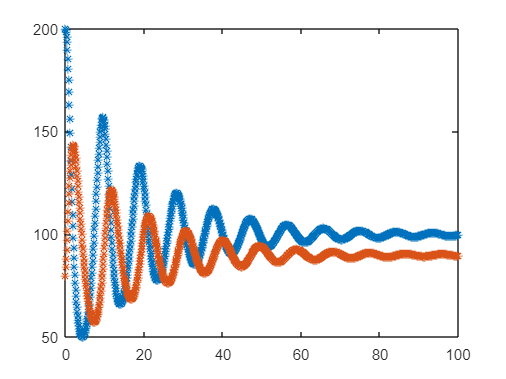

plot(X,Y,"*")

syms A B  C D E F   t
y_ss1 = A*EV1(:,1)*exp(ev1(1,1)*t) + B*EV1(:,2)*exp(ev1(2,2)*t)

$$y\_ss1 = \left(\begin{array}{c} A\,{\mathrm{e}}^{b_{1}\,t}\\ B\,{\mathrm{e}}^{-a_{2}\,t} \end{array}\right)$$

y_ss2 = C*EV2(:,1)*exp(ev2(1,1)*t) + D*EV2(:,2)*exp(ev2(2,2)*t)

$$y\_ss2 = \begin{array}{l} \left(\begin{array}{c} \frac{C\,c_{1}\,\sigma_{2}\,\sigma_{4}}{2\,b_{1}\,c_{2}\,k\,\left(c_{2}-a_{2}\,k\right)}+\frac{\text{D}\,c_{1}\,\sigma_{1}\,\sigma_{3}}{2\,b_{1}\,c_{2}\,k\,\left(c_{2}-a_{2}\,k\right)}\\ \text{D}\,\sigma_{1}+C\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{\frac{t\,\sigma_{3}}{2\,c_{2}\,k}}\\ \sigma_{2}={\mathrm{e}}^{\frac{t\,\sigma_{4}}{2\,c_{2}\,k}}\\ \sigma_{3}=3\,a_{2}\,b_{1}-\sigma_{5}\\ \sigma_{4}=3\,a_{2}\,b_{1}+\sigma_{5}\\ \sigma_{5}=\sqrt{a_{2}\,b_{1}\,\left(4\,{c_{2}}^{2}\,k^{2}-4\,a_{2}\,c_{2}\,k^{3}+9\,a_{2}\,b_{1}\right)} \end{array}$$

y_ss3 = E*EV3(:,1)*exp(ev3(1,1)*t) + F*EV3(:,2)*exp(ev3(2,2)*t)

$$y\_ss3 = \left(\begin{array}{c} F\,{\mathrm{e}}^{3\,b_{1}\,t}-\frac{\text{E}\,c_{1}\,k\,{\mathrm{e}}^{-t\,\left(a_{2}-c_{2}\,k\right)}}{a_{2}+3\,b_{1}-c_{2}\,k}\\ \text{E}\,{\mathrm{e}}^{-t\,\left(a_{2}-c_{2}\,k\right)} \end{array}\right)$$

eqn1 = subs(y_ss1(1),[t,a2,b1,c1,c2,k],[0,0.5,1,0.01,0.005,1000]) == 200;
eqn2 = subs(y_ss1(2),[t,a2,b1,c1,c2,k],[0,0.5,1,0.01,0.005,1000]) == 80;
eqn3= subs(y_ss2(1),[t,a2,b1,c1,c2,k],[0,0.5,1,0.01,0.005,1000]) == 200;
eqn4 = subs(y_ss2(2),[t,a2,b1,c1,c2,k],[0,0.5,1,0.01,0.005,1000]) == 80;
eqn5 = subs(y_ss3(1),[t,a2,b1,c1,c2,k],[0,0.5,1,0.01,0.005,1000]) == 200;
eqn6 = subs(y_ss3(2),[t,a2,b1,c1,c2,k],[0,0.5,1,0.01,0.005,1000]) == 80;
sol = solve([eqn1,eqn2,eqn3,eqn4,eqn5,eqn6],[A,B,C,D,E,F])

sol = struct with fields:
    A: 200
    B: 80
    C: (19999791^(1/2)*33333040i)/6666597 + 40
    D: -(19999791^(1/2)*(2499978 + 19999791^(1/2)*1i)*40i)/19999791
    E: 80
    F: -1000/3


y1 = subs(y_ss1,[A,B,a2,b1,c1,c2,k],[sol.A,sol.B,0.5,1,0.01,0.005,1000])

$$y1 = \left(\begin{array}{c} 200\,{\mathrm{e}}^{t}\\ 80\,{\mathrm{e}}^{-\frac{t}{2}} \end{array}\right)$$

y2 = subs(y_ss2,[C,D,a2,b1,c1,c2,k],[sol.C,sol.D,0.5,1,0.01,0.005,1000])

$$y2 = \begin{array}{l} \left(\begin{array}{c} -\frac{\sigma_{3}\,\sigma_{5}\,\sigma_{1}}{499995}-\frac{8\,\sqrt{19999791}\,\sigma_{2}\,\sigma_{4}\,\left(2499978+\sqrt{19999791}\,\mathrm{i}\right)\,\mathrm{i}}{1999959100209}\\ \sigma_{3}\,\sigma_{1}-\frac{40\,\sqrt{19999791}\,\sigma_{2}\,\left(2499978+\sqrt{19999791}\,\mathrm{i}\right)\,\mathrm{i}}{19999791} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=40+\frac{33333040\,\sqrt{19999791}\,\mathrm{i}}{6666597}\\ \sigma_{2}={\mathrm{e}}^{-\frac{t\,\sigma_{4}}{10}}\\ \sigma_{3}={\mathrm{e}}^{\frac{t\,\sigma_{5}}{10}}\\ \sigma_{4}=-\frac{3}{2}+\frac{\sqrt{19999791}\,\mathrm{i}}{2}\\ \sigma_{5}=\frac{3}{2}+\frac{\sqrt{19999791}\,\mathrm{i}}{2} \end{array}$$

y3 = subs(y_ss3,[E,F,a2,b1,c1,c2,k],[sol.E,sol.F,0.5,1,0.01,0.005,1000])

$$y3 = \left(\begin{array}{c} \frac{1600\,{\mathrm{e}}^{\frac{9\,t}{2}}}{3}-\frac{1000\,{\mathrm{e}}^{3\,t}}{3}\\ 80\,{\mathrm{e}}^{\frac{9\,t}{2}} \end{array}\right)$$

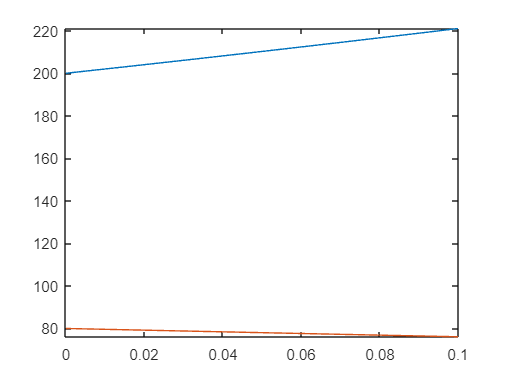

clf
fplot(y1,[0 0.1])

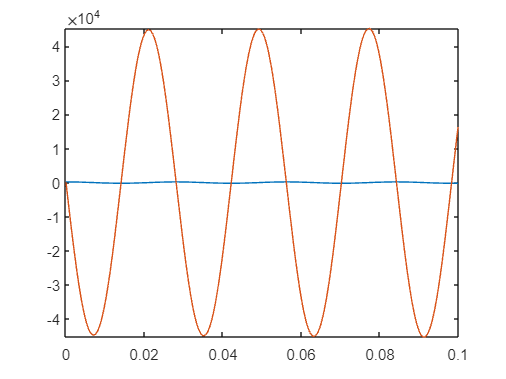

fplot(y2,[0 0.1])

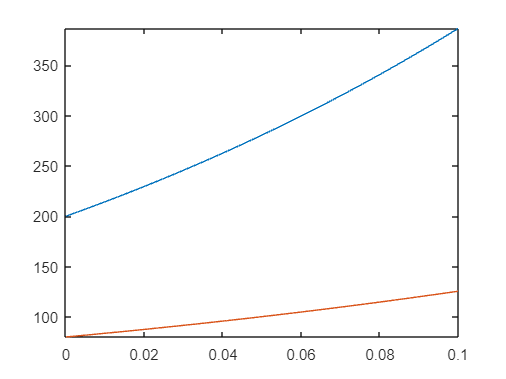

fplot(y3,[0 0.1])